# Optimization objectives prediction from RTDose object

Intent of this code is to predict optimization objectives from Mvision dose prediction RTDose for input to a 3rd party optimizer (MatRad or TPS)

[MVision Dose prediction](https://plan.demo.mvision.ai)

### Select DICOM data

We assume only one patient in the selected folder (1 CT series, 1 RTDOSE, 1 RTSTRUCT)

InputDir=uigetdir("C:\Users\mylly");
[~, caseName, ~] = fileparts(InputDir);
s=dicomCollection(InputDir);
RTSFile=s.Filenames{s.Modality=="RTSTRUCT"};
RTDFile=s.Filenames{s.Modality=="RTDOSE"};
[CT,RCT,infct,Tr]=readDCMSeriesFromFiles(s.Filenames{s.Modality=="CT"});

### Read RTDose

R is the spatial reference object, infrd contains dicom metadata, D is the dose matrix in Gy

[D,R,infrd,~]=readDCMRTDoseFromFile(RTDFile);
orthosliceViewer(D,"Colormap",jet,"ScaleFactors",[1,1,R.PixelExtentInWorldZ/R.PixelExtentInWorldX]);
title(infrd.PatientID);

### Calculate DVHs

Reading contours from RSTRUCT file

infrs=dicominfo(RTSFile,"UseDictionaryVR",true,"UseVRHeuristic",false);
c=dicomContours(infrs);
fn=fieldnames(infrs.RTROIObservationsSequence);
T=table('Size',[numel(fn),2],'VariableTypes',{'double','string'},'VariableNames',{'ROINumber','ROIInterpretedType'});
for ii=1:numel(fn)
    T(ii,:)=table(infrs.RTROIObservationsSequence.(fn{ii}).ReferencedROINumber,string(infrs.RTROIObservationsSequence.(fn{ii}).RTROIInterpretedType));
end

Filter contour one only one slice and keep only EXTERNAL, ORGAN, AVOIDANCE & PTV ROIs

g=cellfun(@numel,c.ROIs.ContourData);
ixd=unique([c.ROIs.Number(g==1);T.ROINumber(not(matches(T.ROIInterpretedType,["EXTERNAL","ORGAN","AVOIDANCE","PTV"])))]);
if not(isempty(ixd))
    c=deleteContour(c,ixd);
    T(ismember(T.ROINumber,ixd),:)=[];
end
c.ROIs

ans = 9×5 table
    Number          Name          ContourData     GeometricType       Color    
    ______    ________________    ____________    _____________    ____________

       2      {'Bag_Bowel'   }    {157×1 cell}    {157×1 cell}     {3×1 double}
       3      {'Bladder'     }    { 31×1 cell}    { 31×1 cell}     {3×1 double}
       4      {'Femur_L'     }    { 43×1 cell}    { 43×1 cell}     {3×1 double}
       5      {'Femur_R'     }    { 46×1 cell}    { 46×1 cell}     {3×1 double}
       6      {'PTV_5000'    }    { 77×1 cell}    { 77×1 cell}     {3×1 double}
       7      {'Penilebulb'  }    {  6×1 cell}    {  6×1 cell}     {3×1 double}
       9      {'Rectosigmoid'}    { 15×1 cell}    { 15×1 cell}     {3×1 double}
      10      {'Rectum'      }    { 37×1 cell}    { 37×1 cell}     {3×1 double}
      12     

We assume that only one body contour in the RTSTRUCT file.

We caculate DVH at 1mm isotropic resolution

DoseGridResmm=1;

z=(cellfun(@(x)(x(1,3)),c.ROIs.ContourData{upper(c.ROIs.Name)=="BODY" | upper(c.ROIs.Name)=="EXTERNAL"},"UniformOutput",true));
st=median(abs(diff(z)));
startZ=min(z);
endZ=max(z);

Rs=imref3d(fix([size(D,[1,2]).*R.PixelExtentInWorldX/DoseGridResmm,size(D,3).*R.PixelExtentInWorldZ/st]),DoseGridResmm,DoseGridResmm,st);

Rs.XWorldLimits=R.XWorldLimits(1)+[0,diff(Rs.XWorldLimits)];
Rs.YWorldLimits=R.YWorldLimits(1)+[0,diff(Rs.YWorldLimits)];
[~,ix]=min(abs(z-R.ZWorldLimits(1)));
Rs.ZWorldLimits=z(ix)+[0,diff(Rs.ZWorldLimits)];

ps=max(Rs.ImageSize(1:2));
Rt=imref3d([max(Rs.ImageSize(1:2)),max(Rs.ImageSize(1:2)),Rs.ImageSize(3)],Rs.PixelExtentInWorldX*Rs.ImageSize(2)/max(Rs.ImageSize(1:2)),Rs.PixelExtentInWorldY*Rs.ImageSize(1)/max(Rs.ImageSize(1:2)),Rs.PixelExtentInWorldZ);
Rt.XWorldLimits=Rs.XWorldLimits;
Rt.YWorldLimits=Rs.YWorldLimits;
Rt.ZWorldLimits=Rs.ZWorldLimits;


Dose resampling to new spatial reference object

Dt=imwarp(D,R,affinetform3d,"linear","FillValues",0,"OutputView",Rt);
DVH=rowfun(@(x)calcTPSDVH(c,Dt,x,Rt),c.ROIs,"InputVariables","Name","OutputVariableNames",{'DVHx','DVHy','ROIVolume','gEUD'},"ExtractCellContents",true);
DVH=[c.ROIs(:,"Name"),DVH];
DVH.InDoseFlag=rowfun(@(x)inDose(c,x,R),DVH,"InputVariables","Name","OutputFormat","uniform");

%remove targets
DVH=DVH(not(matches(DVH.Name,"PTV"+optionalPattern(digitsPattern)+"_"+digitsPattern)),:);
DVH(:,["Name","ROIVolume","gEUD"])

ans = 8×3 table
          Name          ROIVolume       gEUD    
    ________________    _________    ___________

    {'Bag_Bowel'   }     4717.8      1×15 double
    {'Bladder'     }     330.06      1×15 double
    {'Femur_L'     }     186.57      1×15 double
    {'Femur_R'     }     187.97      1×15 double
    {'Penilebulb'  }     4.6481      1×15 double
    {'Rectosigmoid'}     13.042      1×15 double
    {'Rectum'      }     54.218      1×15 double
    {'Body'        }      30583      1×15 double


% save DVH
% writetable(DVH,sprintf("%s.csv",infrd.PatientID));

### Display DVH curves

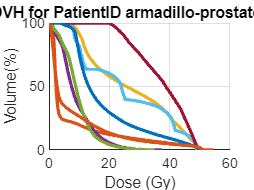

figure(2);
hold on
grid on
rowfun(@(x,y)(plot(x,y,LineWidth=2)),DVH,"InputVariables",["DVHx","DVHy"],"ExtractCellContents",true);
ylabel("Volume(%)");
xlabel("Dose (Gy)");
title(sprintf("DVH for PatientID %s",infrd.PatientID),"Interpreter","none");

### Predict IMRT objectives

We assume that prescription dose is stated in cGy in PTV name (e.g. PTV_6000)

PrescDose=max(str2double(extract(string(c.ROIs.Name(ismember(c.ROIs.Number,T.ROINumber(T.ROIInterpretedType=="PTV")))),digitsPattern(2,4))))/100;
OARs = string(c.ROIs.Name(ismember(c.ROIs.Number,T.ROINumber(T.ROIInterpretedType=="ORGAN"))));
ObjList = ["geud1", "geud3", "maxdose"];
DVHt=DVH(ismember(DVH.Name, OARs),:);
Obj = cell(size(OARs, 1), 3);

for ii=1:height(DVHt)
    %ObjList=Obj.ObjFunction{Obj.ROIName == DVHt.Name(ii)};
    ObjValues = zeros(size(ObjList, 1), 1);
    for jj=1:numel(ObjList)
        if matches(ObjList(jj),"geud"+digitsPattern(1,2))
            a=str2double(extract(ObjList(jj),digitsPattern));
            Val=interp1(1:15,DVHt.gEUD(ii,:),a,"linear");
        end
        if contains(ObjList(jj),"maxdose")
            level = 0.01;
            if min(DVHt.DVHy{ii}) > level
                Val = max(DVHt.DVHx{ii});
            else
                [~,Val]=crossing(DVHt.DVHy{ii},DVHt.DVHx{ii}, level);
                Val = Val(1);
                disp(Val);
            end
        end
        if contains(ObjList(jj),"maxdvh")
            dose=str2double(extract(ObjList(jj),digitsPattern))/100*PrescDose;
            Val=interp1(DVHt.DVHx{ii},DVHt.DVHy{ii},dose);
        end
        ObjValues(jj) = Val;
    end
    Obj{ii, 1} = OARs(ii);
    Obj{ii, 2} = ObjList;
    Obj{ii, 3} = ObjValues;
end

   51.6453

   51.0656

   34.5362

   33.1246

   51.2380

   50.2492

   50.7802



## **Load ct cube, structures and dose with matRad**

[ct, cst, dose] = getPlanFromDicomFolder(InputDir, PrescDose);

Dose series matched to the different plans are displayed and could be selected.
Rechecking of correct matching procedure is recommended.
Progress: 0.53 %  MException with properties:

    identifier: 'MATLAB:nonExistentField'
       message: 'Unrecognized field name "ReferencedDoseSequence".'
         cause: {}
         stack: [3×1 struct]
    Correction100.00 %

importing ct-cube...
creating info...Progress: 100.00 %
reading slices...Progress: 100.00 %

z-coordinates taken from ImagePositionPatient

Interpolating CT cube...finished!

conversion of ct-Cube to Hounsfield units...finished!

Reading structures...finished!


predictedDose = dose.physicalDose;

## Define pln struct

pln.machine = 'Generic';
pln.numOfFractions = 1;
pln.propStf.numOfBeams = 11;
pln.propStf.bixelWidth = 5;
pln.radiationMode = 'photons';
pln.propOpt.runDAO = 1;
pln.propOpt.runSequencing = 1;
pln.propOpt.bioOptimization = 'none';
pln.propStf.couchAngles = zeros(pln.propStf.numOfBeams, 1);
pln.propStf.gantryAngles = zeros(pln.propStf.numOfBeams, 1);
pln.propStf.isoCenter = ones(pln.propStf.numOfBeams, 1) * matRad_getIsoCenter(cst, ct);
for i = 1:pln.propStf.numOfBeams
    pln.propStf.gantryAngles(i) = round((i - 1) * 360 / pln.propStf.numOfBeams);
end

m=createMask(c,T.ROINumber(T.ROIInterpretedType=="PTV"),RCT);
rp=regionprops(m,"Centroid");
pln.propStf.isoCenter=repmat(rp.Centroid.*[RCT.PixelExtentInWorldX,RCT.PixelExtentInWorldY,RCT.PixelExtentInWorldZ],[numel(pln.propStf.gantryAngles),1])

pln = struct with fields:
           machine: 'Generic'
    numOfFractions: 1
           propStf: [1×1 struct]
     radiationMode: 'photons'
           propOpt: [1×1 struct]


## Generate stf (matRad steering information struct)

stf = matRad_generateStf(ct, cst, pln);

matRad: Generating stf struct... 

Progress: 100.00 %


## Find ROI indices and prescribed dose

bodyIndex = find(ismember(cst(:, 2), {'External', 'Body'}));
ptvIndex = find(startsWith(cst(:, 2), 'PTV'), 1);
doseMask = cst{bodyIndex, 4}{1};
ptvMask = cst{ptvIndex, 4}{1};
ptvBinaryMask = false(ct.cubeDim);
ptvBinaryMask(ptvMask) = true;

## **Create optimization problem for conventional objectives (cst)**

cstConv = cst;

for i = 1:size(cst,1)
    for j = 1:size(Obj, 1)
        if strcmp(cst{i,2}, Obj{j, 1})
            objectives = Obj{j, 2};
            values = Obj{j, 3};
            nObjs = size(objectives, 2);
            matRadObjectives = cell(1, nObjs);
            for k = 1:size(objectives, 2)
                if strcmp(objectives(k), "maxdose")
                    matRadObjective = DoseObjectives.matRad_MaxDVH;
                    matRadObjective.parameters = {values(k), 1};
                elseif strcmp(objectives(k), "maxdvh20")
                    matRadObjective = DoseObjectives.matRad_MaxDVH;
                    matRadObjective.parameters = {0.2 * PrescDose, values(k)*100};
                elseif matches(objectives(k), "geud"+digitsPattern(1,3))
                    matRadObjective = DoseObjectives.matRad_MaxEUD;
                    a = str2double(extract(objectives(k), digitsPattern));
                    matRadObjective.parameters = {values(k), a};
                end
                matRadObjectives{k} = matRadObjective;
            end
            cstConv{i, 6} = matRadObjectives;
            break;
        end
    end
end

## Add normal tissue objectives for voxels outside and near the PTV for better conformity

cstConv = add_ntos(cstConv, ct.resolution, ptvBinaryMask, PrescDose);

## Calculate dose

dij = matRad_calcPhotonDose(ct, stf, pln, cst);

matRad: Photon dose calculation...
Beam 1 of 11:
matRad: calculate radiological depth cube... done.
	SSD = 886 mm ...
	Uniform primary photon fluence -> pre-compute kernel convolution...
Progress: 100.00 %
Beam 2 of 11:
matRad: calculate radiological depth cube... done.
	SSD = 875 mm ...
	Uniform primary photon fluence -> pre-compute kernel convolution...
Progress: 100.00 %
Beam 3 of 11:
matRad: calculate radiological depth cube... done.
	SSD = 849 mm ...
	Uniform primary photon fluence -> pre-compute kernel convolution...
Progress: 100.00 %
Beam 4 of 11:
matRad: calculate radiological depth cube... done.
	SSD = 832 mm ...
	Uniform primary photon fluence -> pre-compute kernel convolution...
Progress: 100.00 %
Beam 5 of 11:
matRad: calculate radiological depth cube... done.
	SSD = 828 mm ...
	Uniform primary photon fluence -> pre-compute kernel convolution...
Progress: 100.00 %
Beam 6 of 11:
matRad: calculate radiological depth cube... done.
	SSD = 880 mm ...
	Uniform primary photon flu

## Optimize fluence with predicted optimization objectives and run leaf sequencing

[result, optimizer] = matRad_fluenceOptimization(dij, cstConv, pln);

  matRad_OptimizerIPOPT with properties:

       options: [1×1 struct]
       wResult: []
    resultInfo: []
           env: 'MATLAB'
      showPlot: 1


Optimzation initiating...
Press q to terminate the optimization...

******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************

This is Ipopt version trunk, running with linear solver ma57.

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:   

result = matRad_siochiLeafSequencing(result, stf, dij, 10, false);

## Run direct aperture optimization

  matRad_OptimizerIPOPT with properties:

       options: [1×1 struct]
       wResult: []
    resultInfo: []
           env: 'MATLAB'
      showPlot: 1


Optimzation initiating...
Press q to terminate the optimization...

******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************

This is Ipopt version trunk, running with linear solver ma57.

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:    21848
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:   

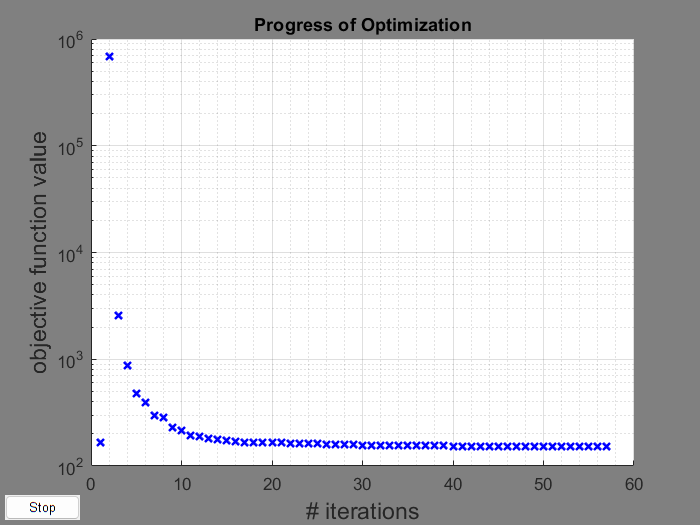

  56  1.5086286e+02 0.00e+00 7.67e-01  -4.5 6.64e-02    -  1.00e+00 2.65e-01f  1

Number of Iterations....: 56

                                   (scaled)                 (unscaled)
Objective...............:   1.5086286303999884e+02    1.5086286303999884e+02
Dual infeasibility......:   7.6667093252530871e-01    7.6667093252530871e-01
Constraint violation....:   0.0000000000000000e+00    0.0000000000000000e+00
Complementarity.........:   1.7871486440893466e-04    1.7871486440893466e-04
Overall NLP error.......:   7.6667093252530871e-01    7.6667093252530871e-01


Number of objective function evaluations             = 58
Number of objective gradient evaluations             = 57
Number of equality constraint evaluations            = 0
Number of inequality constraint evaluations          = 58
Number of equality constraint Jacobian evaluations   = 0
Number of inequality constraint Jacobian evaluations = 57
Number of Lagrangian Hessian evaluations             = 0
Total CPU secs in IPOPT (w/

[result, optimizer] = matRad_directApertureOptimization(dij, cstConv, result.apertureInfo, result, pln);


optimizedDose = result.physicalDose;

## Calculate metrics

ci95 = calcCi(optimizedDose, doseMask, ptvMask, PrescDose, 0.95);
ci50 = calcCi(optimizedDose, doseMask, ptvMask, PrescDose, 0.5);
hi = calcHi(optimizedDose, ptvMask);
[means, maxima] = calcOARMetrics(cst, optimizedDose, OARs);

## Form the problem for voxel based full dose matrix mimicking

fullVoxelCst = cst;

fullVoxelCst{bodyIndex, 6} = {DoseObjectives.matRad_VoxelSquaredOverdosing};
fullVoxelCst{bodyIndex, 6}{1}.penalty = 1;
fullVoxelCst{bodyIndex, 6}{1}.dose = predictedDose;

fullVoxelCst{ptvIndex, 6} = {DoseObjectives.matRad_VoxelSquaredDeviation};
fullVoxelCst{ptvIndex, 6}{1}.penalty = 5;
fullVoxelCst{ptvIndex, 6}{1}.dose = predictedDose;

[result, optimizer] = matRad_fluenceOptimization(dij, fullVoxelCst, pln);
result = matRad_siochiLeafSequencing(result, stf, dij, 5);
[result, optimizer] = matRad_directApertureOptimization(dij, fullVoxelCst, result.apertureInfo, result, pln);

fullVoxelDose = result.physicalDose;

## Calculate metrics for full voxel based dose

fullVoxelCi95 = calcCi(fullVoxelDose, doseMask, ptvMask, PrescDose, 0.95);
fullVoxelCi50 = calcCi(fullVoxelDose, doseMask, ptvMask, PrescDose, 0.5);
fullVoxelHi = calcHi(fullVoxelDose, ptvMask);
[fullVoxelMeans, fullVoxelMaxima] = calcOARMetrics(cst, fullVoxelDose, OARs);

## Form the problem for partial voxel based mimicking (restricted to target and OARs)

partialVoxelCst = cst;

for i = 1:size(cst, 1)
    if i ~= bodyIndex
        if i == ptvIndex
            partialVoxelCst{i, 6} = {DoseObjectives.matRad_VoxelSquaredDeviation};
            partialVoxelCst{i, 6}{1}.penalty = 5;
            partialVoxelCst{i, 6}{1}.dose = predictedDose;
        else
            partialVoxelCst{i, 6} = {DoseObjectives.matRad_VoxelSquaredOverdosing};
            partialVoxelCst{i, 6}{1}.penalty = 1;
            partialVoxelCst{i, 6}{1}.dose = predictedDose;
        end
    end
end

[result, optimizer] = matRad_fluenceOptimization(dij, partialVoxelCst, pln);
result = matRad_siochiLeafSequencing(result, stf, dij, 5);
[result, optimizer] = matRad_directApertureOptimization(dij, partialVoxelCst, result.apertureInfo, result, pln);

partialVoxelDose = result.physicalDose;

## Calculate metrics for partial voxel based dose

partialVoxelCi95 = calcCi(partialVoxelDose, doseMask, ptvMask, PrescDose, 0.95);
partialVoxelCi50 = calcCi(partialVoxelDose, doseMask, ptvMask, PrescDose, 0.5);
partialVoxelHi = calcHi(partialVoxelDose, ptvMask);
[partialVoxelMeans, partialVoxelMaxima] = calcOARMetrics(cst, partialVoxelDose, OARs);

## **Form the problem for voxel based dose mimicking with target objective (Hybrid 1)**

hybrid1cst = fullVoxelCst;
hybrid1cst{ptvIndex, 6} = {DoseObjectives.matRad_SquaredDeviation};
hybrid1cst{ptvIndex, 6}{1}.penalty = 20;
hybrid1cst{ptvIndex, 6}{1}.parameters = {PrescDose}

[result, optimizer] = matRad_fluenceOptimization(dij, hybrid1cst, pln);
result = matRad_siochiLeafSequencing(result, stf, dij, 5);
[result, optimizer] = matRad_directApertureOptimization(dij, hybrid1cst, result.apertureInfo, result, pln);

hybrid1dose = result.physicalDose;

## Calculate metrics for hybrid 1

hybrid1ci95 = calcCi(hybrid1dose, doseMask, ptvMask, PrescDose, 0.95);
hybrid1ci50 = calcCi(hybrid1dose, doseMask, ptvMask, PrescDose, 0.5);
hybrid1hi = calcHi(hybrid1dose, ptvMask);
[hybrid1means, hybrid1maxima] = calcOARMetrics(cst, hybrid1dose, OARs);

## **Form the problem for voxel based dose mimicking with target objective and normal tissue objectives (Hybrid 2)**

hybrid2cst = add_ntos(hybrid1cst, ct.resolution, ptvBinaryMask, PrescDose);

[result, optimizer] = matRad_fluenceOptimization(dij, hybrid2cst, pln);
result = matRad_siochiLeafSequencing(result, stf, dij, 5);
[result, optimizer] = matRad_directApertureOptimization(dij, hybrid2cst, result.apertureInfo, result, pln);

hybrid2dose = result.physicalDose;

## Calculate metrics for hybrid 2

hybrid2ci95 = calcCi(hybrid2dose, doseMask, ptvMask, PrescDose, 0.95);
hybrid2ci50 = calcCi(hybrid2dose, doseMask, ptvMask, PrescDose, 0.5);
hybrid2hi = calcHi(hybrid2dose, ptvMask);
[hybrid2means, hybrid2maxima] = calcOARMetrics(cst, hybrid2dose, OARs);

## Calculate metrics for predicted dose

predictionCi95 = calcCi(predictedDose, doseMask, ptvMask, PrescDose, 0.95);
predictionCi50 = calcCi(predictedDose, doseMask, ptvMask, PrescDose, 0.5);
predictionHi = calcHi(predictedDose, ptvMask);
[predictionMeans, predictionMaxima] = calcOARMetrics(cst, predictedDose, OARs);

## Collect the results

HomogeneityIndex = [predictionHi hi fullVoxelHi partialVoxelHi hybrid1hi hybrid2hi];
ConformityIndex95 = [predictionCi95 ci95 fullVoxelCi95 partialVoxelCi95 hybrid1ci95 hybrid2ci95];
ConformityIndex50 = [predictionCi50 ci50 fullVoxelCi50 partialVoxelCi50 hybrid1ci50 hybrid2ci50];
OARMeans = [predictionMeans means fullVoxelMeans partialVoxelMeans hybrid1means hybrid2means];
OARMaxima = [predictionMaxima maxima fullVoxelMaxima partialVoxelMaxima hybrid1maxima hybrid2maxima];
OARStacked = zeros(2 * size(OARMeans, 1), size(OARMeans, 2));
meansRowNames = arrayfun(@(x) [x{1}, ' mean'], OARs, 'UniformOutput', false);
maximaRowNames = arrayfun(@(x) [x{1}, ' max'], OARs, 'UniformOutput', false);
OARRowNames = strings(2 * size(meansRowNames, 1), 1);
for i = 1:size(meansRowNames, 1)
    OARRowNames(2 * i - 1) = meansRowNames(i);
    OARStacked(2 * i - 1, :) = OARMeans(i, :);
    OARRowNames(2 * i) = maximaRowNames(i);
    OARStacked(2 * i, :) = OARMaxima(i, :);
end
combined = [HomogeneityIndex; ConformityIndex95; ConformityIndex50; OARStacked];
metrics = array2table(combined);
metrics.Properties.VariableNames = {'Predicted Dose', 'Conventional Optimized Dose', 'Full Voxel Mimicking', 'Labels Voxel Mimicking', 'Hybrid 1', 'Hybrid 2'};
metrics.Properties.RowNames = ['Hi'; 'Ci95'; 'Ci50'; OARRowNames];
writetable(metrics, [caseName '_results.csv'], 'WriteRowNames', true);
dosesFileName = [caseName '_doses.mat'];
save(dosesFileName, "predictedDose", "optimizedDose", "fullVoxelDose", "partialVoxelDose", "hybrid1dose", "hybrid2dose")

### Resampling dose grid to CT series geometry

Dct is the matrix rewritten to CT FOR UID

[CT,RCT,infct]=readDCMSeriesFromFiles(s.Filenames{s.Modality=="CT"});
figure(3)
sliceViewer(CT,"DisplayRange",[-150,350]);
title(infrd.PatientID);
Dct=imwarp(hybrid2dose,R,affinetform3d,"linear","FillValues",0,"OutputView",RCT);

% figure(4)
% orthosliceViewer(D,"Colormap",jet,"ScaleFactors",[1,1,R.PixelExtentInWorldZ/R.PixelExtentInWorldX]);
% title(infrd.PatientID);

## Internal functions

### Calculate DVH from dose and contours

function [DVHx,DVHy,RoiVolume,gEUD]=calcTPSDVH(c,D,x,Rs)
    EUD=@(v,d,a)sum(v.*d.^a)^(1/a); 
    BinWidthGy=0.1;
    m=createMask(c,x,Rs);

    if sum(m,"all")>0
        d=D(m);
        
        [n,edges]=histcounts(d,0:BinWidthGy:(fix(max(d).*1.05/BinWidthGy)+1)*BinWidthGy);
        DVHx=edges(1:end-1)+BinWidthGy/2;   
        
        DVHy=flip(cumsum(flip(n)));
        DVHy= 100 * DVHy./numel(d);
        
        RoiVolume=sum(m,"all").*Rs.PixelExtentInWorldX.*Rs.PixelExtentInWorldY.*Rs.PixelExtentInWorldZ/1000;
        a=1:15;
        gEUD=arrayfun(@(a)EUD(n/numel(d),DVHx,a),a);
        %gEUD=[EUD(,DVHx,1),EUD(n/numel(d),DVHx,3),EUD(n/numel(d),DVHx,10)];
        
        DVHx={DVHx};
        DVHy={DVHy};
    else
        DVHx={NaN};
        DVHy={NaN};
        RoiVolume=0;
        gEUD=[];
    end
end

### Check if ROI is in dose

function Flag=inDose(c,x,R)
    cd=c.ROIs.ContourData{string(c.ROIs.Name)==x};
    z=cellfun(@(x)max(x(:,3)),cd);
    ix=z>=min(R.ZWorldLimits) & z<=max(R.ZWorldLimits);
    Flag=sum(ix)==numel(z);
end